# Classifying Human Activity Data

                             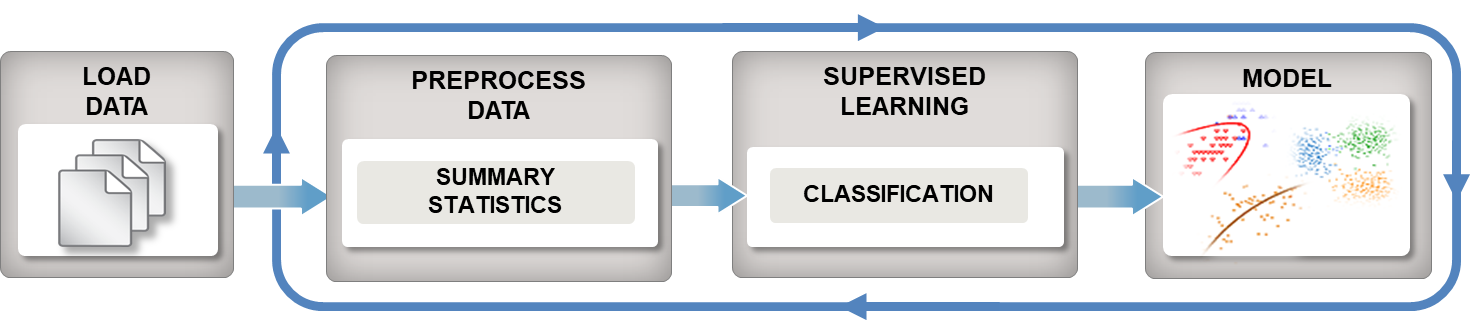

This algorithm uses human activity sensor data containing measurements taken from smartphones worn by people while doing 5 different activities (walking, sitting, laying etc). The goal of this analysis is to extract useful features from the raw buffered data and build a model to automatically identify the activity type given the sensor measurements.

The dataset can be found [here](https://archive.ics.uci.edu/ml/datasets/human+activity+recognition+using+smartphones):

`Dataset Courtesy:`` Davide Anguita, Alessandro Ghio, Luca Oneto, Xavier Parra and Jorge L. Reyes-Ortiz. A Public Domain Dataset for Human Activity Recognition Using Smartphones. 21th European Symposium on Artificial Neural Networks, Computational Intelligence and Machine Learning, ESANN 2013. Bruges, Belgium 24-26 April 2013. `

## Download and load buffered data

The data takes the form of accelerometer values taken over time along with correct activity label and the subject number. We will use data from 25 subjects as our training dataset, 3 subjects as our validation set and 2 subjects as our testing set. 

We can't operate on a single data point alone, but instead we work with overlapping buffers of data. These buffers are 2.56 seconds long and occur every 1.28 seconds. So, every 1.28 second we are classifying what activity we were doing for most of the last 2.56 seconds. We have 6873 buffers of 128 points each.

For your convenience, we have downloaded the data and saved it in a file. If you choose to download the data live, please note it may take few minutes.

clear variables
addpath(genpath(pwd));

downloadDataLive = false; % true: extract the features live

if downloadDataLive
    nTrain = 25;
    nValidate = 3;
    nTest = 2;
    [trainData,validateData,testData] = prepareData(nTrain,nValidate,nTest); 
    
else
    load bufferedData.mat
end

## Extract statistical features 

Let's start with extracting basic statistical features. We will create a new table that contains the correct label and the mean and standard deviation of each buffer. Since our data was organized with each buffer along a row, this can be done with a few simple commands, calculating the mean and standard deviations for the signal in the X, Y, and Z direction.

trainFeatures = table;
trainFeatures.activity = trainData.activity;
trainFeatures.Xmean = mean(trainData.X,2);
trainFeatures.Xstd = std(trainData.X,[],2);

% TO DO: <<< Entered code here >>>
trainFeatures.Ymean = mean(trainData.Y,2);
trainFeatures.Ystd = std(trainData.Y,[],2);
trainFeatures.Zmean = mean(trainData.Z,2);
trainFeatures.Zstd = std(trainData.Z,[],2);


## Train a machine learning model (interactively)

One of the biggest challenges in machine learning is there are many different machine learning algorithms that could be applied to the same problem, and there is no way of knowing ahead of time which will work best. The Classification Learner App gives us an easy way to try out many different modeling techniques very quickly.

**TO DO: **

- **Run the Classification Learner App with the trainFeatures dataset. **

- **Export the best model you can find into the MATLAB Workspace.**

- **Use the exported model to make predictions for our validation set called validateFeatures.          **

**Do you see an improvement in model accuracy? **

% TO DO
% 1. Run the classification learner app first: find under Apps tab above,
% or run this line of code to bring up the Classification Learner
% Note: we used "cross validation" with 5 folds to obtain the results below
classificationLearner;

% 2. Export the model from the app (as COMPACT model), e.g. to "trainedModel" 

% 3. To validate the model, we extract the same features from the validation set as the training set. 
validateFeatures = table;

% concatenate the original validation and test set, since both separately were too small
validateData = [validateData;testData]; 

validateFeatures.activity = validateData.activity;
validateFeatures.Xmean = mean(validateData.X,2);
validateFeatures.Ymean = mean(validateData.Y,2);
validateFeatures.Zmean = mean(validateData.Z,2);
validateFeatures.Xstd = std(validateData.X,[],2);
validateFeatures.Ystd = std(validateData.Y,[],2);
validateFeatures.Zstd = std(validateData.Z,[],2);


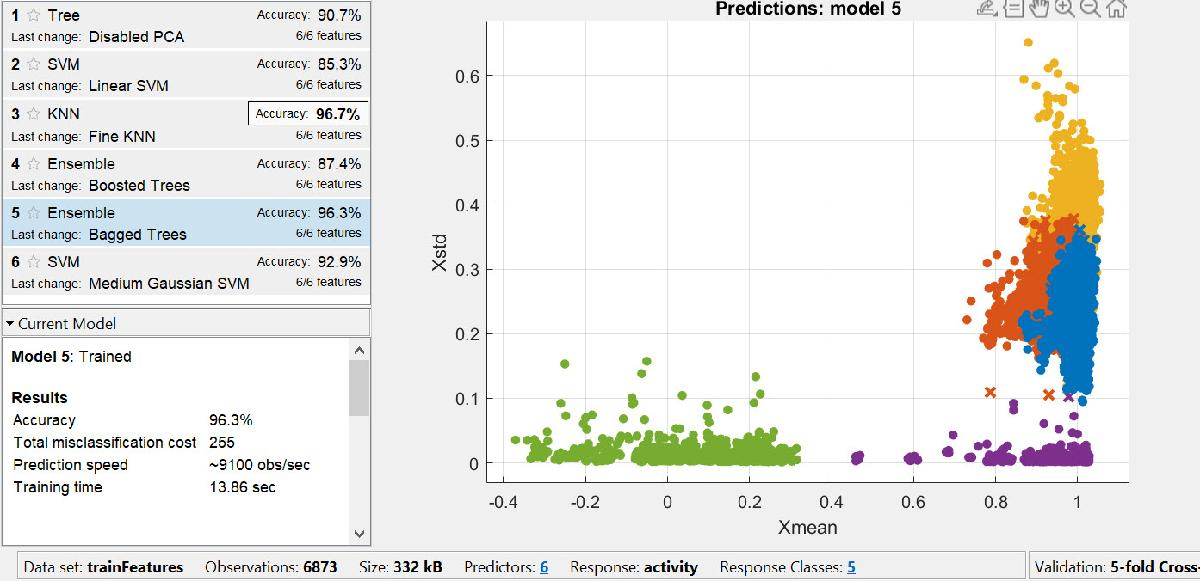

% 4. evaluate accuracy on the held-out validation data
% TO DO: <<< ENTERED code here >>>
newPred1 = trainedModel.predictFcn(validateFeatures);

% Calculate accuracy 
accuracy1 = sum(validateFeatures.activity == newPred1) / numel(validateFeatures.activity) * 100

accuracy1 = 78.4868

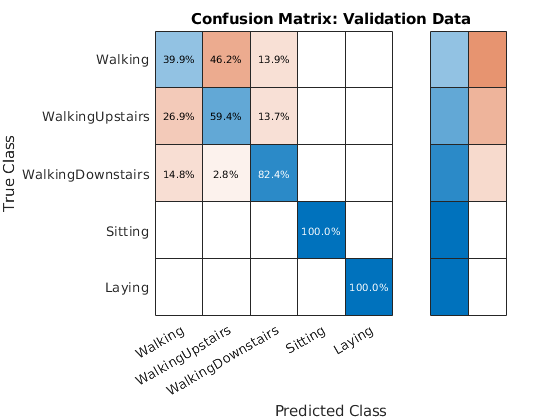


% Plot confusion chart 
confusionchart(validateFeatures.activity, newPred1, 'RowSummary','row-normalized',...
    'Normalization','row-normalized','Title','Confusion Matrix: Validation Data');

## Optimize model using hyperparameter tuning 

Another powerful tool for improving model accuracy is hyperparameter optimization. Hyperparameters are the parameters we set on how to train the model. Note that in this example there are a number of combinations that have very similar accuracy results, so depending on the particular random numbers that are generated the best hyperparameters could change slightly. For more information on Bayesian optimization with MATLAB, [click here](matlab:web(fullfile(docroot, 'stats/bayesian-optimization-workflow.html'))).

With R2019b, this process is available directly in the Classification Learner. Simply select one of the "Optimizable" models from the model gallery, adjust the Advanced "Optimizer Options" appropriately (set a time limit to, say, 5 mins, or limit the #iterations so you won't get stuck in a 10+ min tuning process), and click "Train" like before. The display will show a progress plot of the classification error, along with current hyperparameter settings. For more information in our documentation, [click here](matlab:web(fullfile(docroot, 'stats/hyperparameter-optimization-in-classification-learner-app.html'))).

**TO DO:**

- **Optimize hyperparameters onone of the models you tried above inside the app: choose the corresponding "Optimizable" model from the gallery **(see screenshot below)**, and hit "Train"**

- **Did accuracy improve? **(If not, don't be worried, hyperparameter tuning does not always help)

- (Optional) optimize hyperparameters on a couple models and select the best one

- **Evaluate accuacy of the (best) tuned model on validation data, using the code below. Compare the accuracy for training and validation dataset. Does higher accuracy in training dataset  indicate a good validation accuracy? **

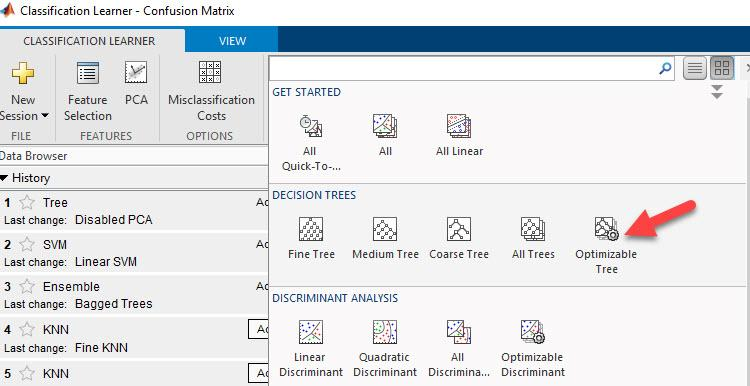

% Evaluate accuracy of model with optimized hyperparameters
% <<< MODIFIED code  >>>
% Note: export optimized model from the Classification Learner, as (COMPACT) "optimizedModel"
newPred2 = optimizedModel.predictFcn(validateFeatures);

% Calculate accuracy 
accuracy2 = sum(validateFeatures.activity == newPred2) / numel(validateFeatures.activity) * 100

accuracy2 = 85.5263

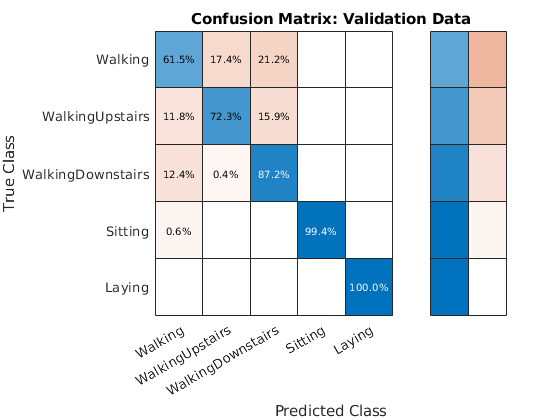


% Plot confusion chart 
confusionchart(validateFeatures.activity, newPred2, 'RowSummary','row-normalized',...
    'Normalization','row-normalized','Title','Confusion Matrix: Validation Data');

## Conclusion

What is the highest accuracy that you get? - If you haven't already, create a table comparing accuracies of various models, cross-validation (inside the Learner App) versus on the held-out validation data, and trained on just mean and standard deviation on buffers versus with tuned hyperparameters. What does it mean that accuracy of the hyperparameter tuned model on held-out data isn't always better than the untuned model? 

In most cases, model does a good job of predicting 'Sitting' and 'Laying' acitvities but it fails to distinguish between walking, walking upstairs and walking downstairs. This indicates we need to do something different to further improve accuracy. In the next module (03), we will create additional features. What other characteristics of the signals can we explore? Later in module 04, we will question how to approach this classification problem.

In our full Machine Learning workshop or training that we provide, you can learn more about the various algorithms, and trade-offs you can make. Below table summarizes the key algorithms' main characteristics. If you rather not get deeper into machine learning, you could try the new one-step model selection and parameter optimization function  [fitcauto](matlab:web(fullfile(docroot, 'stats/fitcauto.html'))), which takes a set of features, and defined responses, and tries out all reasonable models all the while tuning their hyperparameters. That will take a while on this dataset, therefore it's not suitable in the context of this workshop, but you can try it out on your own.